# Control ELCN304 Project

By

Andew Amir Ramses

Nour El-Din Khaled

Omar Tarek Ahmed Mohamed Ali Amer 1180004

Youssef Alaa

## Question 1

### Requirement 1

Due to the amplifier, we have


$$V_a =50\;V_i \;\;\;\;\;\;\;\left(0\right)$$


And by writing the KVL equation on the motor circuit we get


$$V_a ={\textrm{Ri}}_a +e_{b\;} \;\;\;\;\;\;\left(1\right)$$



$$\textrm{Where}\;e_b \;\textrm{is}\;\textrm{the}\;\textrm{back}\;\textrm{emf}\ldotp$$


We know that the back emf is proportional to the angular velocity of the motor, this yields equation no. 2


$$V_a ={\textrm{Ri}}_a +K_b \dot{\theta} \;\;\;\;\;\left(2\right)$$


And from Newton's second law we can obtain equation no.3


$$\left(J_m +J_l \right)\ddot{\theta} =K_T i_a$$



$$\textrm{Where}\;J_{m\;} \textrm{is}\;\textrm{the}\;\textrm{motor}\;\textrm{inertia},\textrm{and}\;J_l \;\textrm{is}\;\textrm{the}\;\textrm{load}\;\textrm{inertia}\ldotp$$



$$\textrm{And}\;\textrm{since}\;J_m =J_l \;,\textrm{we}\;\textrm{can}\;\textrm{say}\;\textrm{that}\;J_m +J_l =2J\;\textrm{which}\;\textrm{gives}\;\textrm{us}$$



$$2J\ddot{\theta} =K_T i_a \;\;\;\;\;\;\left(3\right)$$


And from the given equations:


$$\begin{array}{l}
q_o =51\;h\left(t\right)\;\;\;\;\;\;\left(4\right)\\
q_1 =82\;\theta \;\;\;\;\;\;\;\;\;\;\;\left(5\right)
\end{array}$$


And if we apply the tank equations, we get equations no. 6 and 7


$$\begin{array}{l}
q_1 -q_o =A\;\frac{d}{\mathrm{d}t}h\;\;\;\;\;\;\left(6\right)\\
h=q_0 \;R_v \;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\left(7\right)
\end{array}$$



$$\textrm{Where}\;R_v \;\textrm{is}\;\textrm{the}\;\textrm{resistance}\;\textrm{value}\;\textrm{of}\;\textrm{the}\;\textrm{valve}\ldotp$$


Plugging equation no.5 into equation no.6 gives us


$$82\;\theta -q_o =A\;\frac{d}{\mathrm{d}t}h\;\;\;\;\;\;\left(8\right)$$


The SSR equations take the form


$$\begin{array}{l}
A\underline{x} +B\underline{u\;} =\underline{\dot{x} } \;\;\;\;\;\;\left(9\right)\\
C\underline{x} +D\underline{u} =\underline{y} \;\;\;\;\left(10\right)
\end{array}$$


We choose the position of the shaft as our first state, its angular velocity as the second, and the level of the tank as the third state. The input of the system is $V_i$ and the output is $h\left(t\right)$.


$$\begin{array}{l}
x_1 =\theta \\
x_2 =\dot{\theta} \\
x_3 =h\left(t\right)
\end{array}$$


We now get the state equations:


$$\dot{x} {\;}_1 =x_2 \;\;\;\;\;\;\left(11\right)$$


From equation no.3


$$\left(2J\right)\ddot{\theta} =K_T i_a \;$$

$$\rightarrow$$

$$\dot{x} {\;}_2 =\frac{K_T }{2J}i_a \;\;\;\;\;\;\left(12\right)$$


We need to get $i_a$ in terms of our chosen states, from equations 0 and 2:


$$\begin{array}{l}
50\;u={\textrm{Ri}}_a +K_b x_2 \\
50\;u-K_b x_2 ={\textrm{Ri}}_a 
\end{array}$$



$$i_a =\frac{-K_b }{R}x_2 +\frac{50}{R}u\;\;\;\;\;\;\left(13\right)$$


We can now go back to equation 12:


$$\dot{x} {\;}_2 =\frac{-K_T K_b }{2\textrm{RJ}}x_2 +\frac{50\;K_T }{2\textrm{RJ}}u\;\;\;\;\;\;\left(14\right)$$


From equations 4, 5, and 6:


$$\dot{\dot{x} {\;}_3 =\frac{82}{A}x_1 -\frac{51}{A}x_3 \;\;\;\;\;\;\left(15\right)}$$


And finally, the output equation is simply


$$y=x_3 \;\;\;\;\;\;\left(16\right)$$


We then substitute into equation 9 and 10, the SSR equations:


$$\underline{\dot{x} } =\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{2\mathrm{RJ}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack \underline{x} +\left\lbrack \begin{array}{c}
0\\
\frac{50k_T }{2\mathrm{RJ}}\\
0
\end{array}\right\rbrack \underline{u}$$
 


$$y=\left\lbrack \begin{array}{ccc}
0 & 0 & 1
\end{array}\right\rbrack \;\underline{x}$$


clc
clear

We then define the system in code in order to use it later

% Definition of constants
kt = 9.5;
kb = 0.0704;
j = 0.0058;
area = 51;
R = 10;

% Definition of SSR matrices A,B,C, and D.
A = [0 1 0; 0 (-kt*kb)/(2*R*j) 0; (82/area) 0 (-51/area)];
B = [0; (50*kt)/(2*R*j); 0];
C = [0 0 1];
D = 0;

% Definition of the main system
sys = ss(A, B, C, D);

### Requirement 2

We need to check the controllability and observability of our system. The formula for controllability and observability matricies are as follows:


$$\textrm{Co}=\left\lbrack \begin{array}{ccccc}
B & \textrm{AB} & A^2 B & \ldotp \ldotp \ldotp  & A^{n-1} B
\end{array}\right\rbrack$$



$$\textrm{Ob}=\left\lbrack \begin{array}{c}
C\\
\textrm{CA}\\
\ldotp \ldotp \ldotp \\
{\textrm{CA}}^{n-1} 
\end{array}\right\rbrack$$



$$\textrm{Where}\;A\;\textrm{is}\;n\times n,\;B\;\textrm{is}\;n\times r,\;\textrm{and}\;C\;\textrm{is}\;m\times n$$


Both $\textrm{Co}$ and $\textrm{Ob}$ need to be of rank $n$ for the system to be controllable and observable respectively. There are built in functions in the *Control System Toolbox* that calculate said matricies for us

Co = ctrb(A, B); % Get the controllability matrix for the system.
rankCo = rank(Co); % Get its rank.

Ob = obsv(A, C); % Get the observability matrix for the system.
rankOb = rank(Ob); % Get its rank.

n = size(A, 1); % A is an n x n matrix. this line gets the value of n.

% Check if the system is controllable or not
if rankCo == n
    fprintf("System is controllable as n = rank(Co) = %d", n)
else
    fprintf("System is not controllable as n doesn't equal rank(Co),\nn = %d\nrank(Co) = %d", n, rankCo)
end

System is controllable as n = rank(Co) = 3


% Check if the system is observable or not
if rankOb == n
    fprintf("System is observable as n = rank(Ob) = %d", n)
else
    fprintf("System is not observable as n doesn't equal rank(Ob),\nn = %d\nrank(Ob) = %d", n, rankOb)
end

System is observable as n = rank(Ob) = 3

### Requirement 3

We need to get the transfer function of our system. This can be easily obtained using the one-liner shown below:

TF = tf(sys)

TF =
 
            6584
  -------------------------
  s^3 + 6.766 s^2 + 5.766 s
 
Continuous-time transfer function.



### Requirement 4

We know the poles of any systems are the eigen values of its A matrix. We can use the formula shown below and solve for lambda to get the eigen values (poles) of the system.


$$|\lambda I\;-\;A|=0$$


From *requirement 1* we know that: 


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-k_T k_b }{\textrm{RJ}} & 0\\
\frac{82}{A} & 0 & -\frac{51}{A}
\end{array}\right\rbrack$$


And after plugging in the values of all constants, we get


$$A=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & \frac{-836}{145} & 0\\
\frac{82}{51} & 0 & -1
\end{array}\right\rbrack$$


We now get the eigen values of the A matrix:

poles = eig(A)

poles =    -1.0000
         0
   -5.7655


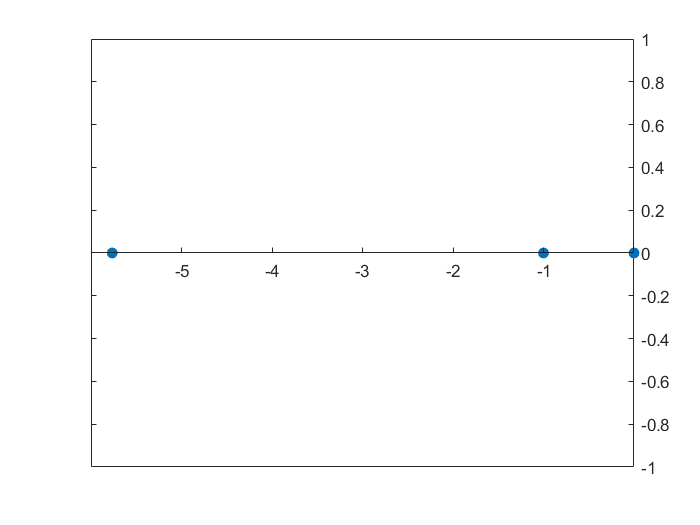

% Plot the poles
stem(real(poles),imag(poles), 'filled')
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

Denoted by the blue dots are the poles of our system.

Having a pole at the origin makes the system critically stable.

### Requirement 5

When we operate the system with $V_i =1\;V$ we get the following response:

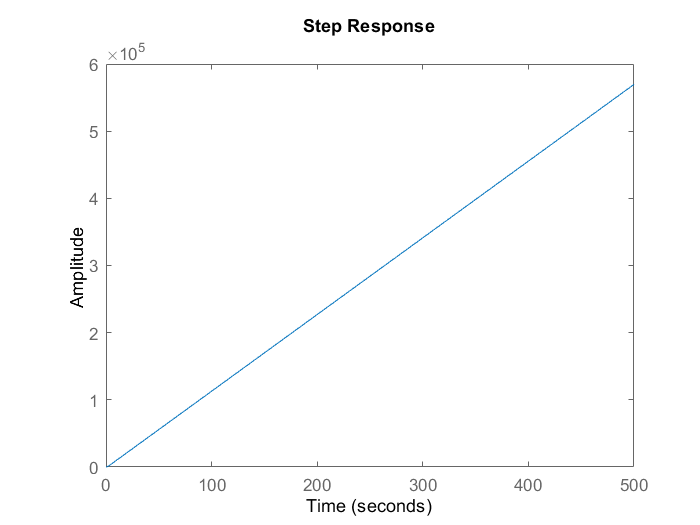

step(sys)

Here we can see that the system has no steady state value for a step input. This is because the system is critically stable.

### Requirement 6

From req. 5 we can see that a steady state response value for a step input doesnt exist. this can be fixed by adding a DC gain that is less than a certain factor.

In the next code section we attempt to calculate this value.

We know that the stability condition for a third order system


$${a_2 a}_1 >{a_3 a}_0$$


$\mathrm{where}\;a_i \;\mathrm{is}\;\mathrm{the}\;\mathrm{coeffecient}\;\mathrm{of}\;x^i \;\;\mathrm{in}\;\mathrm{the}\;\mathrm{characteristic}\;\mathrm{equation}$.

Before stabilizing the system, the characteristic equation is


$$s^3 +6\ldotp 766s^2 +5\ldotp 766s+6584=0$$


When we apply the condition we can see that


$$6\ldotp 766\times 5\ldotp 766\not> 1\times 6584$$


To find the required gain we solve this simple inequality


$$6\ldotp 766\times 5\ldotp 766>6584K$$



$$\mathrm{where}\;K\;\mathrm{is}\;\mathrm{the}\;\mathrm{stabilizing}\;\mathrm{gain}\;\mathrm{value}\ldotp$$


k = (6.766*5.766) / 6584;
fprintf("Solution: K < %f", k)

Solution: K < 0.005925

We need $K<0\ldotp 005925$. Let $K=0\ldotp 001$

stabilizedSystem = feedback(series(TF, 0.001),1)

stabilizedSystem =
 
                6.584
  ---------------------------------
  s^3 + 6.766 s^2 + 5.766 s + 6.584
 
Continuous-time transfer function.



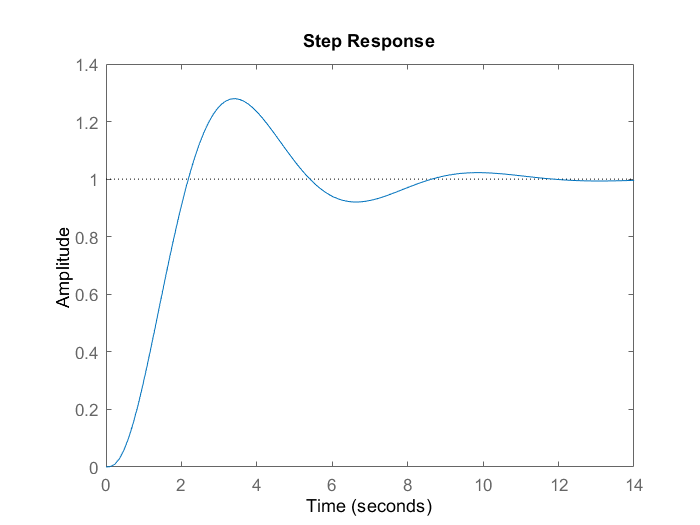

step(stabilizedSystem)

Here we can see that the system is now stable under the effect of a step input.

### Requirement 7

We now study the effect of controlling our system using the controller


$$\frac{G_c \left(s\right)}{s+1000}\;\textrm{where}\;G_c \left(s\right)=1$$


controller = tf([0 1], [1 1000]) % Define the controller

controller =
 
     1
  --------
  s + 1000
 
Continuous-time transfer function.



piCtrlSysFF = controller * TF  % PI controlled system - Feedforward

piCtrlSysFF =
 
                 6584
  ----------------------------------
  s^4 + 1007 s^3 + 6771 s^2 + 5766 s
 
Continuous-time transfer function.



piSys = feedback(piCtrlSysFF, 1)

piSys =
 
                    6584
  -----------------------------------------
  s^4 + 1007 s^3 + 6771 s^2 + 5766 s + 6584
 
Continuous-time transfer function.



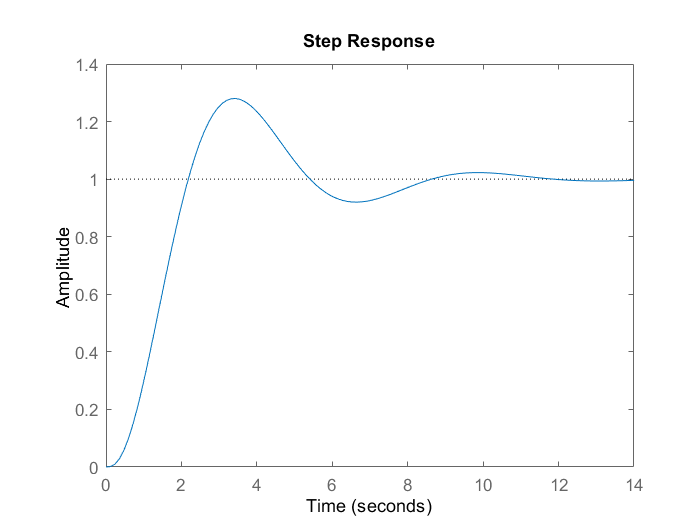

step(piSys)

[y,t]=step(piSys); % Get the response of the system to a step with amplitude SP
sserror=abs(1-y(end)) % Get the steady state error

sserror = 0.0060

### Requirement 8

We need the settling time to be less than 3 secs, and the maximum overshoot to be less than 15%. We now design the controller.

We choose the **PD** controller as we need to enhance the settling time and the overshoot only.

** Draft **

we need to solve for $\zeta \;$and $\omega_n$ 

We know that


$$t_s =\frac{4}{\zeta \omega_n }\;\left(2%\;\textrm{criterion}\right)$$



$$\textrm{and}$$



$$M_p =e^{\frac{-\zeta \pi }{\sqrt{1-\zeta^2 }}}$$


We now solve for $\zeta \;$and $\omega_n$ 

syms zeta;
syms omega;

ts = 4/(zeta*omega) == 3

$$ts = \frac{4}{\omega \,\zeta }=3$$

mp = exp((-zeta*pi)/(1-zeta^2)^(0.5)) == 15/100

$$mp = {\mathrm{e}}^{-\frac{\pi \,\zeta }{\sqrt{1-\zeta^{2}}}}=\frac{3}{20}$$

zeta = eval(solve(mp, zeta,'Real', true))

zeta = 0.5169

omega = eval(solve(ts, omega,'Real', true))

omega = 2.5793

We know that our open loop transfer function takes the form

 
$$\frac{6584}{s^4 +1007s^3 +6771s^2 +5766s}$$


And our controller takes the form:


$$K_p +K_d s$$


So the equation of the feedforward path becomes:

syms K_p K_d s
openLoopTF = 6584/(s^4 + 1007*s^3+6771*s^2+5766*s);
newController = K_p + K_d*s;
disp("After adding the controller, our open loop transfer function looks like this:")

After adding the controller, our open loop transfer function looks like this:


sysAfterControl = openLoopTF * newController

$$sysAfterControl = \frac{6584\,\left(K_{p}+K_{d}\,s\right)}{s^{4}+1007\,s^{3}+6771\,s^{2}+5766\,s}$$

** end draft **

We need the settling time to be less than 3 secs, and the maximum overshoot to be less than 15%. We now start tuning our system. We mainly tune using trial and error.

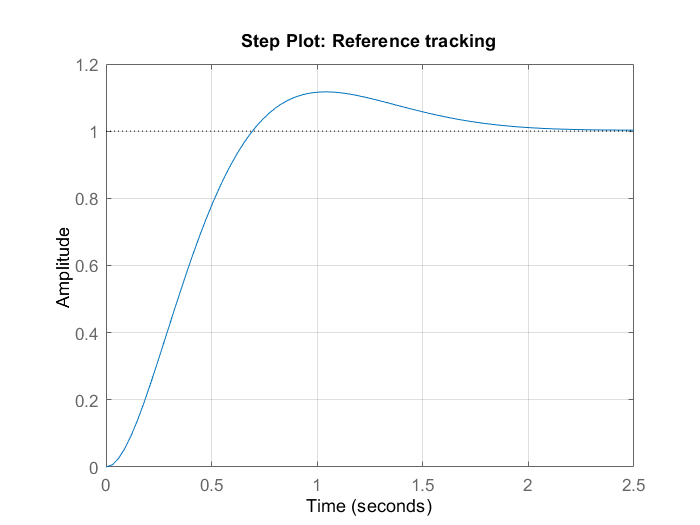

% Convert Response Time to Bandwidth
% Bandwidth is equivalent to 2 divided by the Response Time
wc = 2/0.729191;

% Convert Transient Behavior to Phase Margin
% Phase Margin is equivalent to the Transient Behavior multiplied by 100
PM = 100*0.584263;

% Define options for pidtune command
opts = pidtuneOptions('PhaseMargin',PM);

% PID tuning algorithm for linear plant model
[G_c,pidInfo] = pidtune(piCtrlSysFF,'PD',wc,opts);

% Clear Temporary Variables
clear wc PM opts

% Get desired loop response
Response = getPIDLoopResponse(G_c,piCtrlSysFF,'closed-loop');

% Plot the result
stepplot(Response)
title('Step Plot: Reference tracking')
grid on


% Display system response characteristics
disp(stepinfo(Response))

        RiseTime: 0.4679
    SettlingTime: 1.8317
     SettlingMin: 0.9018
     SettlingMax: 1.1170
       Overshoot: 11.7031
      Undershoot: 0
            Peak: 1.1170
        PeakTime: 1.0369




% Clear Temporary Variables
clear Response

This gives us the follwing the controller:

disp(G_c)

  pid with properties:

              Kp: 3.4048
              Ki: 0
              Kd: 2.5444
              Tf: 0
        IFormula: ''
        DFormula: ''
      InputDelay: 0
     OutputDelay: 0
              Ts: 0
        TimeUnit: 'seconds'
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
    SamplingGrid: [1×1 struct]

